## An implementation of (N)MPC for plasma thermal dose delivery (minimizing treatment time)

created with influences from code by Diogo Rodrigues and [https://web.casadi.org/blog/ocp/](https://web.casadi.org/blog/ocp/) 

(c) Kimberly Chan, Mesbah Lab 2022

clc
close all
clear

## add package paths

addpath(genpath('./utils'))

## user definitions

h = 0.02;    % step size (s)
te = 120.0;  % maximum simulation time (s)

N = 50;     % number of control intervals for the fixed step RK4 integration used in discretizing the system
nx = 2;     % number of states
nu = 1;     % number of inputs

## ---- dynamics -----

constants for plasma model

m1 = 38*2.39;
m2 = 0.003*0.82;
Tinf = 298.15; % K
Tb = 308.15; % K
Rho = 2800.0; % kg m-3
Cp = 795.0; % J kg-1 K-1
d = 0.2e-3; % m
r = 1.5e-3; % m
eta = 0.4;
K = 1.43; % W m-2 K-1
T0 = 310.15; % K
Pmin = 1.0; % W
Pmax = 5.0; % W
Tmax = 316.15; % K
CEMsp = 1.5; % min
km1 = m2*eta/Rho/Cp/pi/r^2/d;
km2 = 2*pi*r*d*K*m1/Rho/Cp/pi/r^2/d*(1/2+(Tmax-Tb)/(Tb-Tinf))*log(1+(Tb-Tinf)/(Tmax-Tb));

% plant model: dxdt = fp(x,u)
fp = @(x,u) [km1*u(1)-km2*((x(1)-Tinf)-(x(1)-Tb))/log((x(1)-Tinf)/(x(1)-Tb));...
            0.5^(43.0+273.15-x(1))/60.0];
% mpc model (with structural mismatch): dxdt = f(x,u)
f = @(x,u) [0.8*km1*u(1)-0.8*2*pi*r*d*K*m1/Rho/Cp/pi/r^2/d*(x(1)-(Tb+Tinf)/2);...
            0.5^(43.0+273.15-x(1))/60.0];

% build prob_info to pass into OCP (see ./utils/controller/MinimumTimeOCP.m
% for more information on how the OCP is designed and formulated in code)
prob_info = struct;
prob_info.nx = nx;
prob_info.nu = nu;
prob_info.f = f;
prob_info.Tmax = Tmax;
prob_info.u_min = Pmin;
prob_info.u_max = Pmax;
prob_info.x0 = [T0; 0.0];
prob_info.xN = [T0; CEMsp];
prob_info.x_init = [T0; 0.0];
prob_info.warm_start = false;

## get OCP

ocp = MinimumTimeOCP(prob_info);
ocp = ocp.get_ocp(N);

## solve OCP

[ocp, res, feas, sol] = ocp.solve_ocp();
% tf = ocp.opti_vars.tf;
% T = ocp.opti_vars.X(1,:);
% CEM = ocp.opti_vars.X(2,:);
% U = ocp.opti_vars.U;
fprintf('Optimal time (open loop): %.4f\n', res.J)

Optimal time (open loop): 111.9399


## simulate with real system (repeatedly compute the OCP in receding horizon fashion)

tout = [0:h:te te];
Nsim = numel(0:h:te);
Xsim = zeros(nx,Nsim+1);
Usim = zeros(nu,Nsim);
Jsim = zeros(1,Nsim);
ctime = zeros(1,Nsim);
params_list = struct;
params_list.XN = prob_info.xN;

Xsim(:,1) = prob_info.x0;
Xsim(1,1) = Xsim(1,1);
ocp = ocp.reset_initial_guesses();

for k = 1:Nsim
    startTime = tic;
    params_list.X0 = Xsim(:,k);
    params_list.X0(1) = params_list.X0(1);
    ocp = ocp.set_parameters(params_list);
    
    [ocp, res, feas, sol] = ocp.solve_ocp();
    ctime(:,k) = toc(startTime);
    
    Usim(:,k) = res.U;
    Jsim(:,k) = res.J;
    
    dxdt = full(fp(Xsim(:,k), Usim(:,k)));
    Xsim(:,k+1) = Xsim(:,k) + h*dxdt;
    if Xsim(2,k+1) > CEMsp
        break
    end
end

CasADi - 2022-01-15 23:34:40 WARNING("solver:nlp_g failed: Inf detected for output g, at (row 2, col 1).") [.../casadi/core/oracle_function.cpp:265]
CasADi - 2022-01-15 23:34:49 WARNING("solver:nlp_g failed: Inf detected for output g, at (row 2, col 1).") [.../casadi/core/oracle_function.cpp:265]


## ---- post processing ------

tout = tout(1:k+1);
T = Xsim(1,1:k+1);
CEM = Xsim(2,1:k+1);
U = Usim(:,1:k);

## plotting

fprintf('Final Simulation Time: %.3f\n', tout(end))

Final Simulation Time: 110.480


fprintf('Final Objective Value: %.3f\n', Jsim(k))

Final Objective Value: 0.610


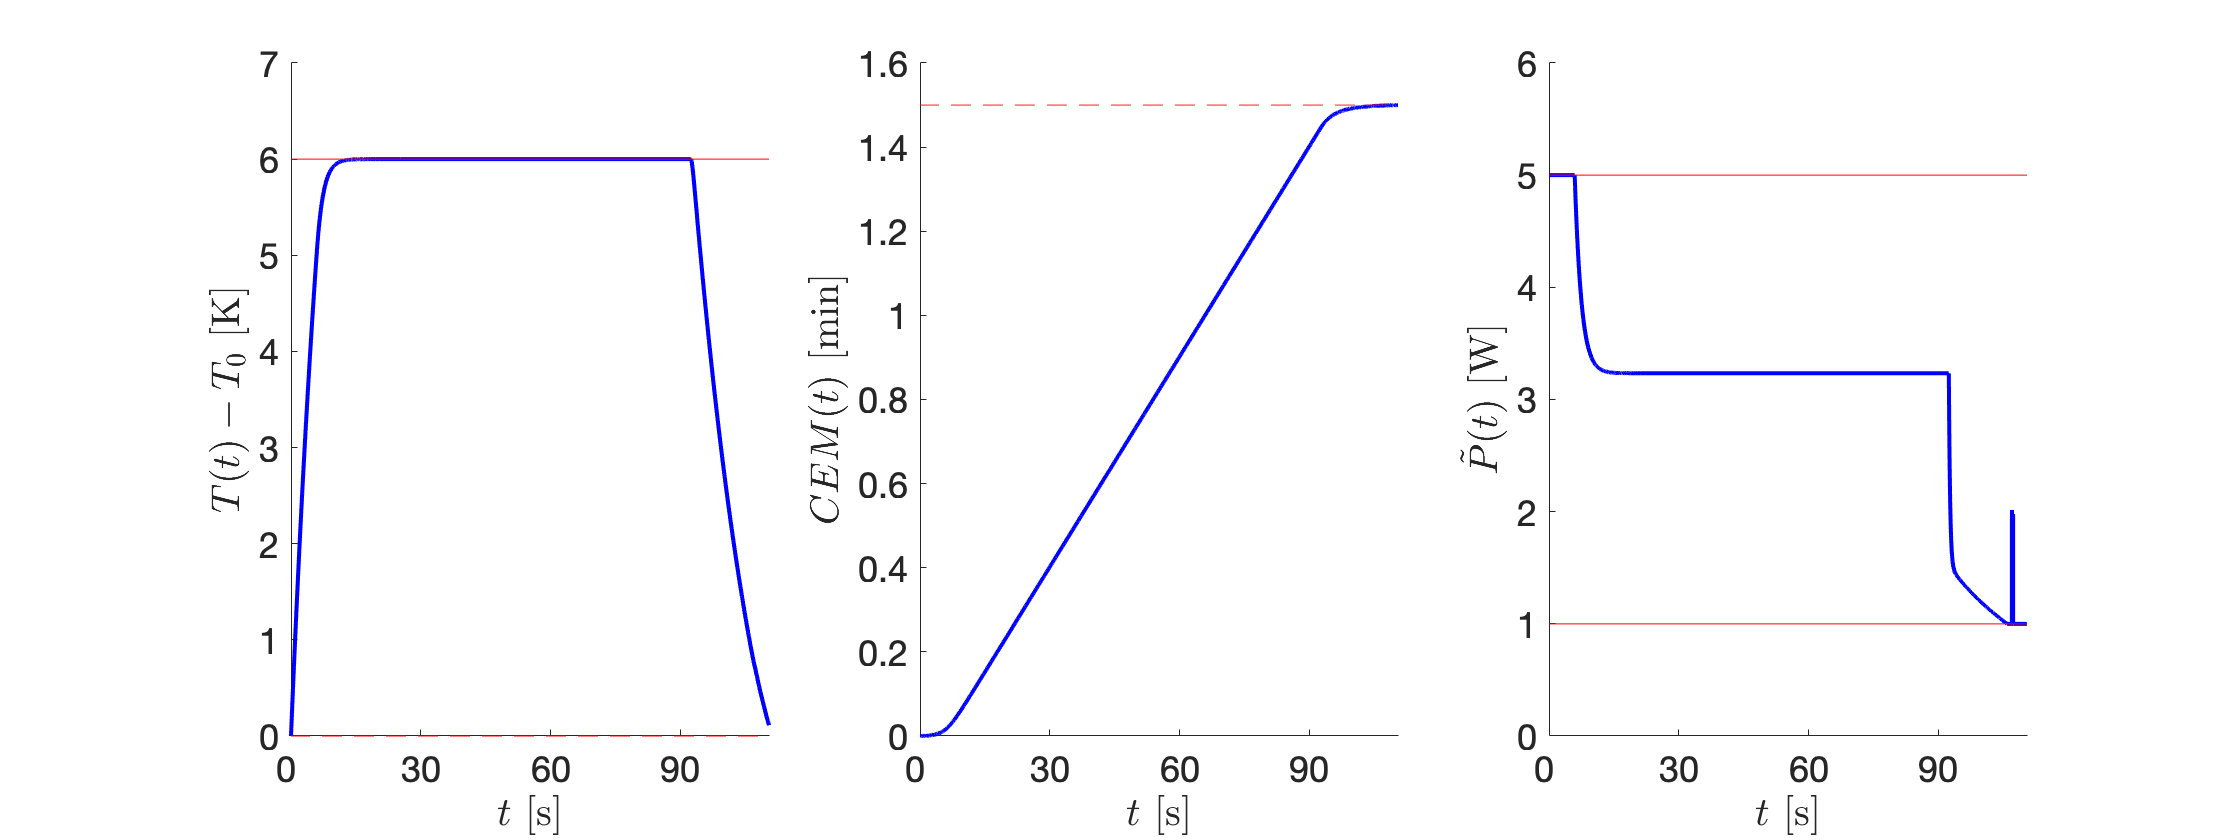


figure()
ax{1} = subplot(1,3,1);
ax{2} = subplot(1,3,2);
ax{3} = subplot(1,3,3);
hold(ax{1},'on'),plot(ax{1},tout,T-T0,'b','LineWidth',2);set(ax{1},'Children',flipud(get(ax{1},'Children')));
hold(ax{1},'on'),plot(ax{1},tout,(Tmax-T0)*ones(size(tout)),'r');
hold(ax{1},'on'),plot(ax{1},tout,zeros(size(tout)),'r--');
title(ax{1},'');ylabel(ax{1},'$T(t)-T_{0}$ [K]','Interpreter','LaTeX','FontSize',20);
p = xlabel(ax{1},'');set(p,'String','$t$ [s]','Interpreter','LaTeX','FontSize',20);
set(ax{1},'FontSize',18,'XTick',0:30:90,'XTickLabel',0:30:90);

hold(ax{2},'on'),plot(ax{2},tout,CEM,'b','LineWidth',2);set(ax{2},'Children',flipud(get(ax{2},'Children')));
hold(ax{2},'on'),plot(ax{2},tout,CEMsp*ones(size(tout)),'r--');
title(ax{2},'');ylabel(ax{2},'$CEM(t)$ [min]','Interpreter','LaTeX','FontSize',20);
p = xlabel(ax{2},'');set(p,'String','$t$ [s]','Interpreter','LaTeX','FontSize',20);
set(ax{2},'FontSize',18,'XTick',0:30:90,'XTickLabel',0:30:90);

hold(ax{3},'on'),plot(ax{3},tout(1:end-1),U,'b','LineWidth',2);set(ax{3},'Children',flipud(get(ax{3},'Children')));
hold(ax{3},'on'),plot(ax{3},tout,Pmin*ones(size(tout)),'r');
hold(ax{3},'on'),plot(ax{3},tout,Pmax*ones(size(tout)),'r');
title(ax{3},'');ylabel(ax{3},'$\tilde{P}(t)$ [W]','Interpreter','LaTeX','FontSize',20);
p = xlabel(ax{3},'');set(p,'String','$t$ [s]','Interpreter','LaTeX','FontSize',20);
set(ax{3},'FontSize',18,'XTick',0:30:90,'XTickLabel',0:30:90);
set(gcf,'Units','normalized'),set(gcf,'OuterPosition',[1,1,2,1].*get(gcf,'OuterPosition'));

## remove paths

rmpath(genpath('./utils'))